Jessica Gallo

CSC747 Digital Signal Processing

Prof. Zhang

October 3, 2020

2.0 Echo Cancellation via Inverse Filtering

In this exercise, you will consider the problem of removing an echo from a recoding of a speech signal. This project will use the audio capabilities of MATLAB to play recordings of both the original speech and the result of your processing. To begin this exercise you will need to load the speech file lineup.mat, which is contained in the Computer Explorations Toolbox. The Computer Explorations Toolbox can be obtained from The MathWroks at the address provided in the Preface. If this speech file is already somewhere in your MATLABPATH, then you can load the data into MATLAB by typing

`>> load lineup.mat`

You can check your MATLABPATH, which is a lsit of all the directories which are currently accessible by MATLAB by typing path. The file `lineup.mat` must be in one of these directories.

    Once you have loaded the data into MATLAB, the speech waveform will be stored in the variable y. Since the speech was recorded witha sampling rate of 8192 Hz, you can hear the speech by typing

`>> sound(y, 8192)`

You should hear the phrase "line up" with an echo. The signal y[n], represented by the vector y, if of the form

$y[n]=x[n]+\alpha x[n-N]$,

where x[n] is the unocrrupted speech signal, which has been delayed by N samples and added back in with its ampltude decreased by $\alpha < 1$. This is a reasonable model for an echo resulting from the signal reflecting off of an absorbing surface like a wall. If a microphone is placed in the center of a room, the recording will contain the speech which travels directly to the microphone, as well as an echo which traveled across the room, relfected off of the far wall, and then into the microphone. Since the echo must travel further, it will be delayed in time. Also, since the speech is particially absorbed by the wall, it will be decreased in amplitude. For simplicity ugnore any further relfections or other sources of echo. 

    For the problems in this exercise, you will use the value of the echo time, N = 1000, and the echo amplitude, $\alpha = 0.5$.

Basic Problems

(a) In this exercise you will remove the echo by linear filtering. SInce the echo can be represented by a linear system of the form Eq 2.21, determine and plot the impulse response of the echo system Eq 2.21. Store this impulse response in the vector `he` for $0 \leq n \leq 1000$.

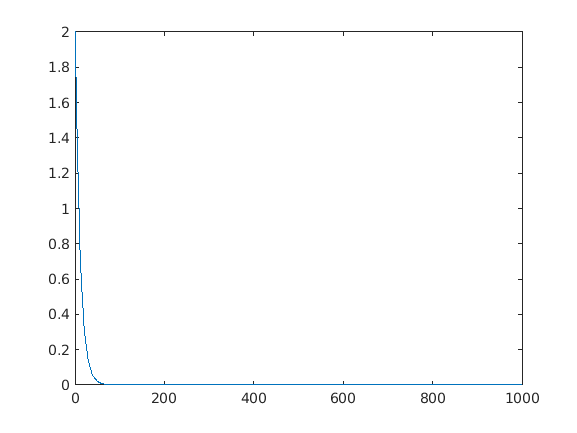

%load lineup.mat
sound(y, 8192);
a = [0.5, 1];
b = 1;
sys = tf(b, a);
he = impulse(sys, 46);
plot(he);

(b) Consider an echo remove system described by the difference equation


$$z[n]+\alpha z[n-N]=y[n]$$


where $y[n]$ is the input and $z[n]$ is the output which has the echo removed. Show that Eq 2.22 is indeed an inverse of Eq 2.21 by deriving the overall difference equation relating $z[n]$ to $x[n]$. Is $z[n] = x[n]$ a valid solution to the overall difference equation?


$$z[n]=x[n]+ax[n]$$



$$z[n] + a z[n-N] = y[n]$$



$$z[n]+az[n-N] = x[n]+ax[n-N]$$



$$z[n]-x[n]=ax[n-N]-az[n-N]$$



$$z[n]-x[n]=a(x[n-N]-z[n-N])$$


$z[n] -x[n] = 0$  =>  $a(x[n-N]-z[n-N]) = 0$

$z[n]=x[n]$  =>  $z[n-N]=x[n-N]$

Intermediate Problems

(c) The echo removal system Eq 2.22 will have an infinite-length impulse reponse. Assuming `N=1000`, and $\alpha = 0.5$, compute the impulse reponse using filter with an input that is na impulse giving by `d=[1 zeros(1, 4000)]`. Store this 4001 sample approximation to the impulse response in the vector her.

d = [1 zeros(1, 4000)];
z = filter(b, a, d);
her = impulse(z, 4000);
sound(z, 8192);

(d) Implement the echo removal system using `z=filter(1, a, y)`, where `a` is the appropriate coefficient vector derived from Eq. 2.22. Plot the output using `plot`. Also, listen to the output using sound. You should no longer hear the echo.

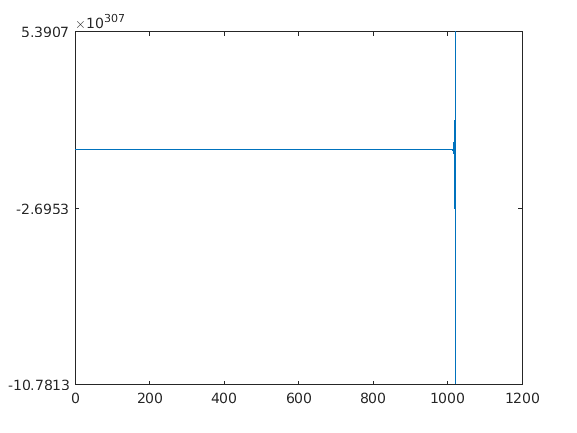

z=filter(1, a, y);
plot(z);
sound(z, 8192);

(e) Calculate the overall impulse response of the cascaded echo system, Eq. 2.21, and echo removeal system E1. 2.22, by convolving `he` with `her` and store the result in `hoa`. Plot the overall impulse reponse. You should notice that the reuslt is not a unit impulse. Given that you have computed her to be the inverse of `he`, why is this the case?

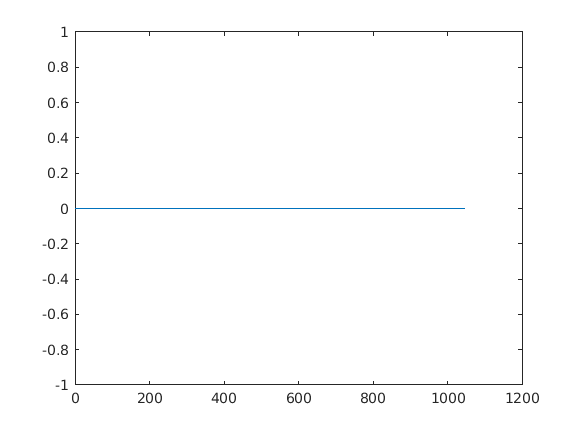

hoa = conv(he, her);
plot(hoa);

The convergence of `he` and `her` on `hoa` is not a unit impulse because as you can see from the plot, there is no unit step or difference in axes, there is just a straight line on 0. A unit impulse is a sequence that is zero except at n=0, where it is unity at discrete time and in continuous time it is infinite in height and zero width but having a finite area. This plot shows a line that starts at 0 and ends at 1000. 

Advanced Problem

(f) Suppose that you were given y[n] but did not know the value of the echo time, N, or the amplitude of the echo, $\alpha$. Based on Eq. 2.21, can you determine a method if estimating these values? Hint: Consider the output y of the echo system to be of the form:


$$y[n]=x[n]*(\delta [n] + \alpha \delta [n-N])$$


and consider the signal,


$$R_{yy} [n] = y[n] * y[-n].$$


This is called the autocorrelation of the signal y[n] and is often used in applications of echo-time estimation. Write $R_{yy}[n]$ in terms of $R_{xx}[n]$ and also plot $R_{yy}[n]$. You will have a truncate y[n] before your calculations to keep $R_{yy}[n]$ while the limitations of the Student Edition of MATLAB. You will find that many of the properties of the autocorrelation will still hold when y is truncated. Also try experimenting with simple echo problems such as

`>> NX=100;`

`>>x=randn(1,NX);`

`>>N=50;`

`>>alpha=0.9;`

`>>y=filter([1, zeros(1,N) alpha, 1 x]);`

`>>Ryy=conv(y, fliplr(y));`

`>>plot([-NX+1:NX-1], Ryy);`

by varying N, alpha, and NX. Also, when you loaded `lineup.mat`, you loaded in two additional vectors. The vetctor y2 contains the phrase "line up" with a different echo time N and different echo amplitude $\alpha$. The vector y3 contains the same phrase with two echoes, each with different times and amplitudes. Can you estimate N and $\alpha$ for y2 and $N_1$, $\alpha_1$, $N_2$, and $\alpha_2$ for y3?


$$R_{yy}[n] = y[n]*y[-n]$$



$$y[n]=x[n]*(\delta[n] + \alpha \delta [n-N])$$



$$R_{yy}[n] = (x[n]*(\delta [n]+ \alpha \delta [n-N]))*(x[-n]*(\delta [-n] + \alpha \delta [-n-N]))$$



$$R_{yy}[n] = (x[n]*x[-n]*(\delta [n]+ \alpha \delta [n-N])*(\delta [-n] + \alpha \delta [-n-N])$$



$$R_{yy}[n] = R_{xx}[n]*(\delta [n]+ \alpha \delta [n-N]))*(\delta [-n] + \alpha \delta [-n-N])$$



$$R_{yy}[n] = R_{xx}[n]*((1+ \alpha^2)\delta[n]+\alpha \delta[n-N]+\alpha \delta [n+N])$$



$$x[n] = \delta[n]$$



$$\alpha = 0.5$$



$$N = 5$$



$$R_{yy}[n] = R_{xx}[n]*((1+0.5^2)\delta[n] + 0.5\delta[n-5] + 0.5\delta[n+5]$$



$$R_{yy}[n] = R_{xx}[n]*(1.25\delta[n] + 0.5\delta[n-5] + 0.5\delta[n+5])$$


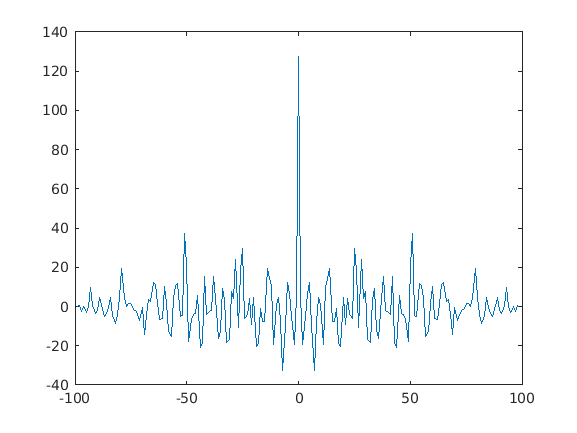

clf;
NX = 100;
x = randn(1, NX);
N = 50;
alpha = 0.9;
y = filter([1 zeros(1, N) alpha], 1, x);
Ryy = conv(y, fliplr(y));
plot(-NX+1:NX-1, Ryy);

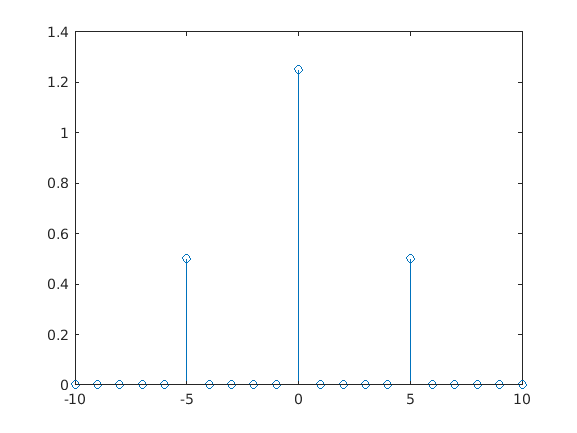

clf;
n = -10:1:10;
alpha = 0.5;
N = 5;
y = [zeros(1, 5), alpha, zeros(1, 4), (1+alpha^2), zeros(1, 4), alpha, zeros(1, 5)];
stem(n, y);

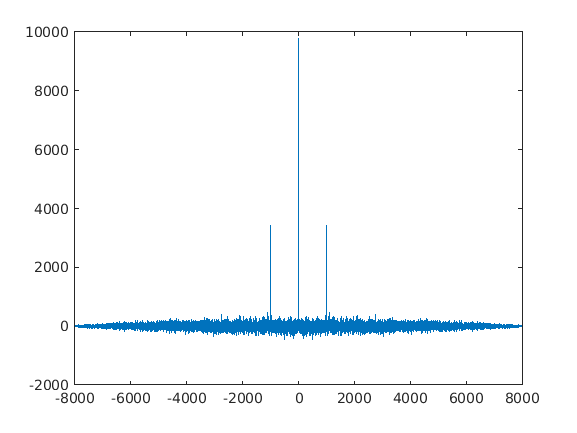

clf;
NX = 8000;
x = randn(1, NX);
N = 1000;
alpha = 0.5;
y = filter([1 zeros(1, N-1) alpha], 1, x);
Ryy = conv(y, fliplr(y));
plot(-NX+1:1:NX-1, Ryy);

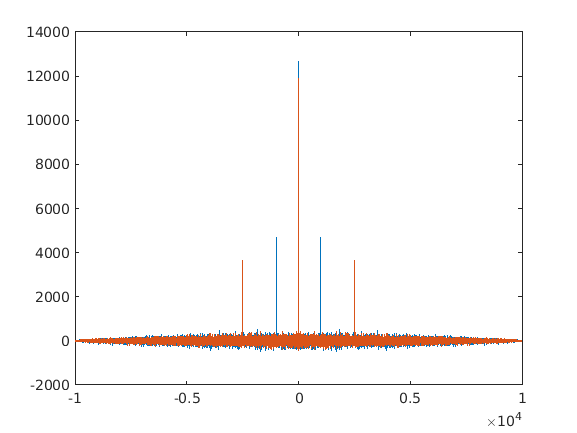

clf;
NX = 10000;
x = randn(1, NX);
alpha = 0.5;
y = filter([1 zeros(1, N-1) alpha], 1, x);
Ryy = conv(y, fliplr(y));
plot(-NX+1:1:NX-1, Ryy);

hold on

NX = 10000;
x = randn(1, NX);
N = 2500;
alpha = 0.5;
y = filter([1 zeros(1, N-1) alpha], 1, x);
Ryy = conv(y, fliplr(y));
plot(-NX+1:1:NX-1, Ryy);